imds=imageDatastore("D:\MY FOLDER\Study\Deep Learninig Computer Vision -Coursera\Data\MathWorks Created\ASL Alphabet\Classification\Train","IncludeSubfolders",true,LabelSource="foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Train\A\A_0006.JPG';
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Train\A\A_0241.JPG';
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Train\A\A_0246.JPG'
                               ... and 597 more
                              }
                     Folders: {
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Train'
                              }
                      Labels: [A; A; A ... and 597 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     Read

[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');

AugTrain=augmentedImageDatastore([224,224],imdsTrain)

AugTrain =   augmentedImageDatastore with properties:

             NumObservations: 480
                       Files: {480×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


AugVal=augmentedImageDatastore([224,224],imdsValidation)

AugVal =   augmentedImageDatastore with properties:

             NumObservations: 120
                       Files: {120×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


opts = trainingOptions("adam","ValidationData",AugVal,"Shuffle","every-epoch","Plots","training-progress","MaxEpochs",20);

net=trainNetwork(AugTrain,lgraph_1,opts)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |        3.91% |       20.00% |       4.0625 |       3.4022 |          0.0010 |
|      17 |          50 |       00:09:38 |      100.00% |       94.17% |       0.0006 |       0.1801 |          0.0010 |


save('Final_Project_Net.mat', 'net');

imdsTest=imageDatastore("D:\MY FOLDER\Study\Deep Learninig Computer Vision -Coursera\Data\MathWorks Created\ASL Alphabet\Classification\Test","IncludeSubfolders",true,"LabelSource","foldernames")
augTest=augmentedImageDatastore([224,224],imdsTest)
Testpreds=classify(net,augTest)
testaccuracy=nnz(Testpreds==imdsTest.Labels)/length(Testpreds)

confusionchart(imdsTest.Labels,Testpreds)

% Specify the folder containing the unlabeled images
unlabeledFolder = 'D:\MY FOLDER\Study\Deep Learninig Computer Vision -Coursera\Data\MathWorks Created\ASL Alphabet\Classification\Unlabeled';

% Create an image datastore
unlabeledImages = imageDatastore(unlabeledFolder, 'IncludeSubfolders', false, 'LabelSource', 'none');


% Preprocess the images
inputSize = [224,224];
augInput=augmentedImageDatastore(inputSize,unlabeledImages)

preictedLabels=classify(net,augInput)

totalImages = numel(imdsTest.Files);
totalImages

% Count the number of images per class
labelCounts = countEachLabel(imdsValidation);

% Display the count of each label
disp(labelCounts);

testASLmodel(net)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |        7.81% |       19.17% |       4.0837 |       3.5063 |          0.0010 |
|      17 |          50 |       00:09:43 |      100.00% |       92.50% |       0.0006 |       0.2736 |          0.0010 |
|      20 |          60 |       00:11:44 |      100.00% |       93.33% |       0.0004 |       0.2626 |          0.0010 |
|=========================================================================================

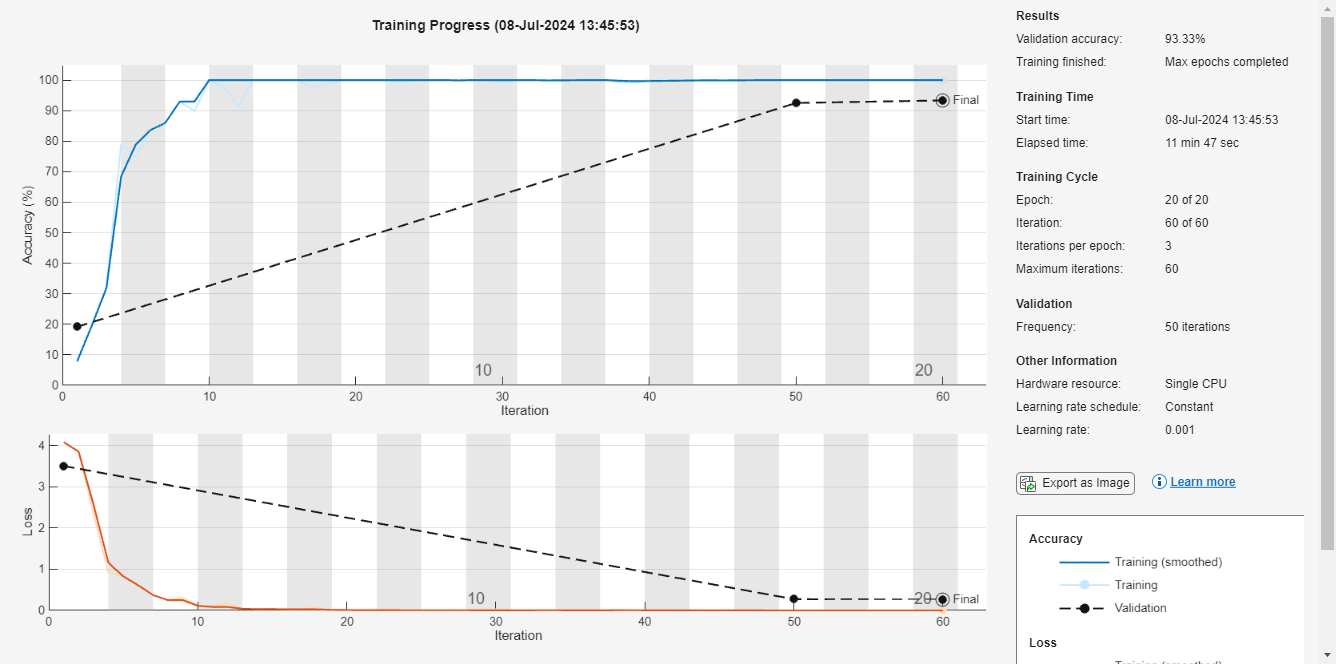

net2 =   DAGNetwork with properties:

         Layers: [71×1 nnet.cnn.layer.Layer]
    Connections: [78×2 table]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


info = struct with fields:
               TrainingLoss: [4.0837 3.8560 2.3585 0.9188 0.8277 0.6097 0.3708 0.2487 0.3084 0.1113 0.0856 0.1929 0.0392 0.0310 0.0383 0.0256 0.0471 0.0609 0.0144 0.0107 0.0066 0.0107 0.0134 0.0049 0.0043 0.0068 0.0112 0.0043 0.0028 … ] (1×60 double)
           TrainingAccuracy: [7.8125 19.5312 32.0312 78.9062 75 83.5938 85.9375 92.9688 89.8438 100 97.6562 91.4062 100 100 100 100 97.6562 98.4375 100 100 100 100 99.2188 100 100 100 100 100 100 99.2188 100 100 100 100 100 100 100 … ] (1×60 double)
             ValidationLoss: [3.5063 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 0.2736 … ] (1×60 double)
         ValidationAccuracy: [19.1667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 

[net2,info]=trainNetwork(AugTrain,lgraph_1,opts)

C = confusionmat(imdsTest.Labels,Testpreds);
% Find letters with the most misclassifications
misclassifiedCounts = sum(C, 2) - max(C, [], 2);
maxMisclassifications = max(misclassifiedCounts);
mostMisclassifiedLetters = find(misclassifiedCounts == maxMisclassifications);

% Convert indices to letters (assuming YVal and YPred are categorical arrays)
letters = categories(imdsTest.Labels);
mostMisclassifiedLettersNames = letters(mostMisclassifiedLetters);

% Display the result
disp(['The most misclassified letter(s) are: ', strjoin(mostMisclassifiedLettersNames, ', ')]);

The most misclassified letter(s) are: M, T
